% Load the dataset
filename = 'synthetic_diabetes_dataset_corrected.csv';
tableData = readtable(filename);

% Extract feature matrix (gene expression levels) and target variable
features = tableData(:, 1:6);  % First six columns are gene expression levels
features = table2array(features); % Convert to numerical array
target = categorical(tableData.Best_Suited_Drug); % Convert target variable to categorical

% Split data into training (80%) and testing (20%)
cv = cvpartition(size(features,1), 'HoldOut', 0.2);
trainData = features(training(cv), :);
testData = features(test(cv), :);
trainLabels = target(training(cv), :);
testLabels = target(test(cv), :);

% Train a Decision Tree model
mdl = fitctree(trainData, trainLabels);

% Predict on test data
predictions = predict(mdl, testData);

% Evaluate model accuracy
accuracy = sum(predictions == testLabels) / length(testLabels);
fprintf('Model Accuracy: %.2f%%\n', accuracy * 100);

Model Accuracy: 100.00%


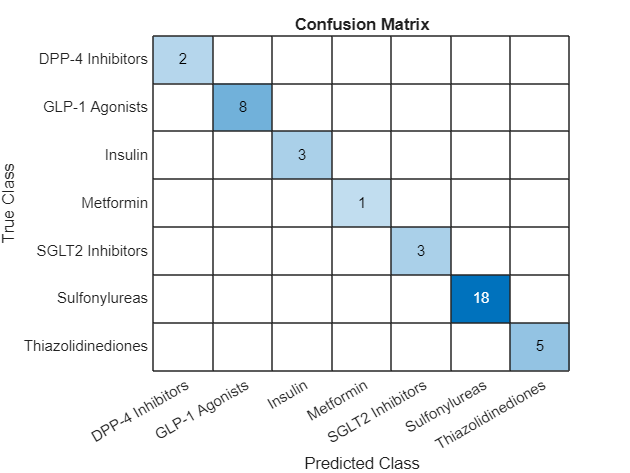


% Display confusion matrix
figure;
confusionchart(testLabels, predictions);
title('Confusion Matrix');


predicted_drug = predict_best_drug(mdl);


Predicted Best-Suited Drug: Sulfonylureas
